clear;
close all;

% Number of setpoints - 1 for the drone between hover points
mu = 3;
% number of set
N_tot = 40;

% Number of setpoints for the drone
K_tot = floor(N_tot/mu); % Number of hover points

alpha_0 = db2pow(-50); % channel power at reference distance d_c(n) = 1m [dB]
N_0 = db2pow(-170e-3); % [dB/Hz]
B = 1e6; % bandwidth [Hz]
sigma_0 = sqrt(N_0 * B); % noise power [dB]
P = db2mag(20e-3); % transmit power [dB]
H = 200; % flying height [m]

x = sym('x',[1 N_tot]);
y = sym('y',[1 N_tot]);
x_c = sym('x_c', [1 1]);
y_c = sym('y_c', [1 1]);

d_c(x,y,x_c,y_c) = sqrt(H^2 + (x-x_c).^2 + (y-y_c).^2);
h_n(x,y,x_c,y_c) = alpha_0 * d_c.^(-2);
inner_log(x,y,x_c,y_c) = 1 + P/sigma_0^2 * h_n;
R_n(x,y,x_c,y_c) = B * log2(inner_log);
R_avg(x,y,x_c,y_c) = 1/N_tot * sum(R_n);

### Calculate the Taylor expasion of first order

% gradients with respect to x
R_avg_gradx(x,y,x_c,y_c) = gradient(R_avg, x).';

% gradients with respect to y
R_avg_grady(x,y,x_c,y_c) = gradient(R_avg, y).';

## Simulation parameter

nu = 0.5;

beta_0 = db2pow(-47); % channel power at reference distance d_s(k) = 1m [dB]
G_p = 0.1 * B; % Signal processing gain [Hz]
V_max = 30; % maximum velocity [m/s]
T_h = 1; % hovering duration [s]
V_str = 20; % [m/s]
mu = 5; %
L_x = 1500; % dimension of the ground in x direction [m]
L_y = 1500; % dimension of the ground in y direction [m]
T_f = 1.5; % flying duration [s]

a = 10; % pre-determined constant related to the system setting

## Simulation Setup

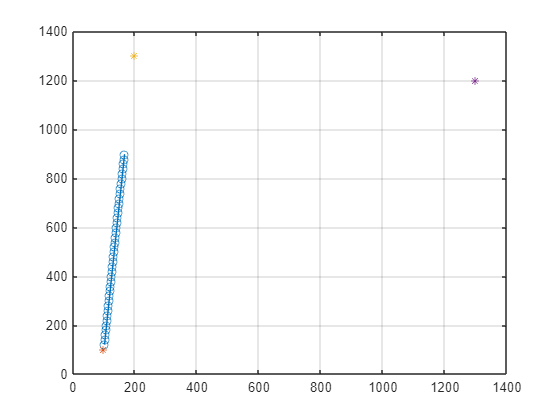

% Basestation
S_s = [100; 100];
% Communication user
S_c = [1.3e3; 1.2e3];
% Sensing target
S_t = [200; 1.3e3];

% target estimation via grid search
S_target_est = S_t + L_x/20*randn(2,1);

% Middle point between communication user und target user
S_mid = (S_c + S_target_est)/2;

% Inital trajectory
[S_traj_init, V_init] = init_trajectory(S_s, N_tot, S_t, V_str, T_f);
plot_trajectory(S_traj_init, S_s, S_t, S_c)

### Parameter for test:

x_in = S_traj_init(1, :);
y_in = S_traj_init(2, :);
x_c_in = S_c(1);
y_c_in = S_c(2);

S_hover = S_traj_init(:, mu:mu:N_tot);

### Test rate

rate_value_sym = double(subs(R_avg, [x,y,x_c,y_c], [x_in, y_in, x_c_in, y_c_in]))

rate_value_sym = 8.0674e-12

rate_value_cf = compute_rate(S_traj_init, S_c, H, N_tot)

rate_value_cf = 0

% Squared difference
(rate_value_sym - rate_value_cf).^2

ans = 6.5083e-23

### Test for distance to sensing target

% symboliv Math tool Box
derivatex_d_c_sym = double(subs(diag(jacobian(d_c, x)), [x,y,x_c,y_c], [x_in, y_in, x_c_in, y_c_in])).'

derivatex_d_c_sym =    -0.7372   -0.7427   -0.7483   -0.7540   -0.7597   -0.7654   -0.7712   -0.7770   -0.7828   -0.7886   -0.7945   -0.8004   -0.8063   -0.8123   -0.8182   -0.8242   -0.8301   -0.8361   -0.8420   -0.8480   -0.8539   -0.8598   -0.8656   -0.8714   -0.8772   -0.8829   -0.8886   -0.8941   -0.8996   -0.9051   -0.9104   -0.9156   -0.9207   -0.9257   -0.9305   -0.9352   -0.9398   -0.9442   -0.9484   -0.9524


% closed form
d_c_cf = compute_dc(S_traj_init, S_c, H, N_tot);
x_c_diff = (S_traj_init(1,:) - S_c(1));
derivatex_dc_cf = x_c_diff ./ d_c_cf

derivatex_dc_cf =    -0.7372   -0.7427   -0.7483   -0.7540   -0.7597   -0.7654   -0.7712   -0.7770   -0.7828   -0.7886   -0.7945   -0.8004   -0.8063   -0.8123   -0.8182   -0.8242   -0.8301   -0.8361   -0.8420   -0.8480   -0.8539   -0.8598   -0.8656   -0.8714   -0.8772   -0.8829   -0.8886   -0.8941   -0.8996   -0.9051   -0.9104   -0.9156   -0.9207   -0.9257   -0.9305   -0.9352   -0.9398   -0.9442   -0.9484   -0.9524


% MSE of the distance to the sensing target
mean((derivatex_d_c_sym - derivatex_dc_cf).^2)

ans = 6.1630e-33

### Test gradient of the rate function

% get double value of the rate
derivatex_rate_sym = double(subs(gradient(R_avg, x), [x,y,x_c,y_c], [x_in, y_in, x_c_in, y_c_in])).'

derivatex_rate_sym = 	1.0e+-15 *

    0.1290    0.1335    0.1382    0.1430    0.1480    0.1531    0.1584    0.1639    0.1696    0.1755    0.1816    0.1878    0.1942    0.2009    0.2077    0.2147    0.2219    0.2293    0.2369    0.2447    0.2527    0.2609    0.2692    0.2777    0.2863    0.2951    0.3041    0.3131    0.3223    0.3316    0.3409    0.3503    0.3598    0.3692    0.3786    0.3880    0.3974    0.4066    0.4157    0.4247


% closed form gradient
gradientx_rate_cf = compute_gradient_rate_x(S_traj_init, S_c, H, N_tot)

gradientx_rate_cf = 	1.0e+-15 *

    0.1290    0.1335    0.1382    0.1430    0.1480    0.1531    0.1584    0.1639    0.1696    0.1755    0.1816    0.1878    0.1942    0.2009    0.2077    0.2147    0.2219    0.2293    0.2369    0.2447    0.2527    0.2609    0.2692    0.2777    0.2863    0.2951    0.3041    0.3131    0.3223    0.3316    0.3409    0.3503    0.3598    0.3692    0.3786    0.3880    0.3974    0.4066    0.4157    0.4247


% MSE of the distance to the sensing target
mean((derivatex_rate_sym - gradientx_rate_cf).^2)

ans = 6.7001e-63

### Test gradient of the rate function

% get double value of the rate
derivatey_rate_sym = double(subs(gradient(R_avg, y), [x,y,x_c,y_c], [x_in, y_in, x_c_in, y_c_in])).'

derivatey_rate_sym = 	1.0e+-15 *

    0.1163    0.1183    0.1203    0.1222    0.1242    0.1261    0.1281    0.1299    0.1318    0.1336    0.1353    0.1370    0.1386    0.1401    0.1416    0.1429    0.1442    0.1453    0.1463    0.1471    0.1478    0.1483    0.1487    0.1488    0.1487    0.1484    0.1479    0.1471    0.1461    0.1447    0.1431    0.1412    0.1389    0.1364    0.1334    0.1302    0.1265    0.1225    0.1182    0.1134


% closed form gradient
gradienty_rate_cf = compute_gradient_rate_y(S_traj_init, S_c, H, N_tot)

gradienty_rate_cf = 	1.0e+-15 *

    0.1163    0.1183    0.1203    0.1222    0.1242    0.1261    0.1281    0.1299    0.1318    0.1336    0.1353    0.1370    0.1386    0.1401    0.1416    0.1429    0.1442    0.1453    0.1463    0.1471    0.1478    0.1483    0.1487    0.1488    0.1487    0.1484    0.1479    0.1471    0.1461    0.1447    0.1431    0.1412    0.1389    0.1364    0.1334    0.1302    0.1265    0.1225    0.1182    0.1134


% MSE of the distance to the sensing target
mean((derivatey_rate_sym - gradienty_rate_cf).^2)

ans = 2.3549e-63